clear
close

small = imread('metallpeque.jpg'); 
big = imread('textures.jpg');

%apliquem filtre gausia per homogeneitzar aver si cuela xd
small = imgaussfilt(small,2);
big = imgaussfilt(big,2);

[small_features, cocmat] = extract_textural_features(small)

small_features =     0.1591    0.1895    0.1610    0.1747
    0.8400    0.8091    0.8381    0.8241
    0.2919    0.2738    0.2907    0.2867
    0.9205    0.9053    0.9195    0.9131


cocmat = cocmat(:,:,1) =

           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0        1046         327           0           0           0           0
           0           0         335       10775        1240           0           0           0
           0           0           0        1309        9529         544           0           0
           0           0           0           0         554        1425           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


cocmat(:,:,2) =

           0           0           0           0           0           0           0           0
           0           0           0           0           0           0          

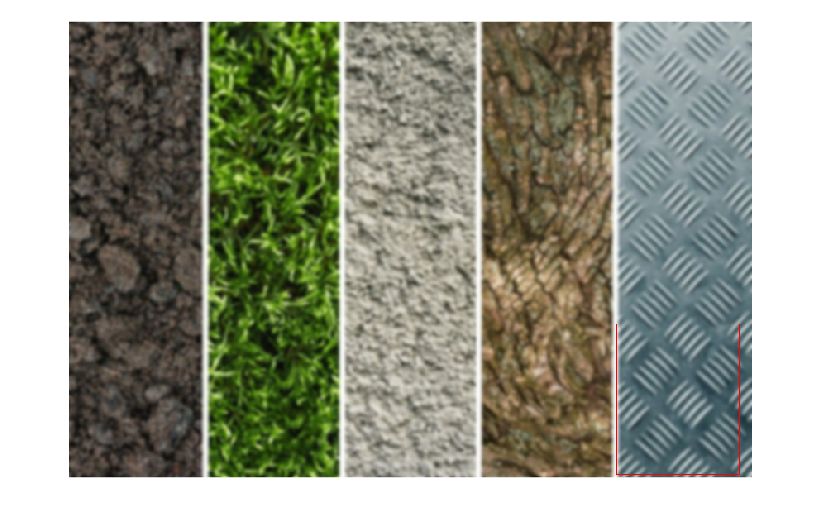


% Suponiendo que tienes las características de textura de la imagen pequeña en 'small_features'
% y la imagen grande en 'imagen_grande'

% Extraer características de textura de la imagen grande
[rows, cols, ~] = size(big);
window_size = size(small);
matching_scores = zeros(rows-window_size(1)+1, cols-window_size(2)+1);

for i = 1:rows-window_size(1)+1
    parfor j = 1:cols-window_size(2)+1
        % Extraer una región de la imagen grande
        region = big(i:i+window_size(1)-1, j:j+window_size(2)-1);
        
        % Calcular características de textura de la región
        region_features = extract_textural_features(region);
        
        % Calcular la distancia entre las características de la región y las características de la imagen pequeña
        matching_scores(i,j) = max(dist(region_features, small_features), [], 'all');
    end
end

% Encontrar la región con la menor distancia
[min_dist, min_idx] = min(matching_scores(:));
[best_row, best_col] = ind2sub(size(matching_scores), min_idx);

% Marcar o identificar la región encontrada
marked_image = insertShape(big, 'Rectangle', [best_col, best_row, window_size(2), window_size(1)], 'Color', 'red');
imshow(marked_image);